# Fourier Transform

[⇦ Fourier Analysis Overview](matlab: OpenOverview)

**Learning Goals**

- Compare Fourier series to the Fourier transform.

- Evaluate the Fourier transform of a function.

- Represent signals using continuous functions.

- Discuss carrier waves and modulation.

- Compare functions in the time and frequency domains using the Fourier transform.

## Introduction

You can use complex Fourier series to analyze periodic functions. Recall the complex Fourier series:


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


By plotting the magnitude of the Fourier coefficients $c_n$, you can identify which frequencies are dominant.

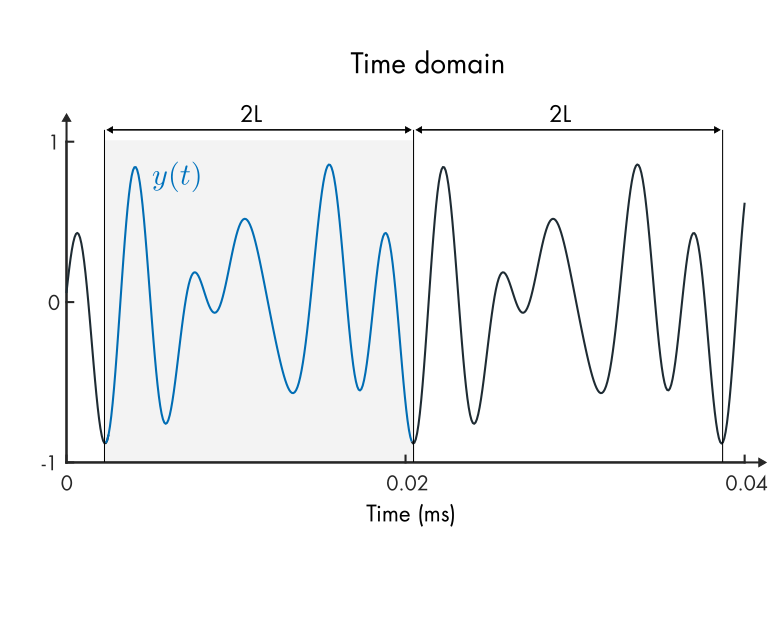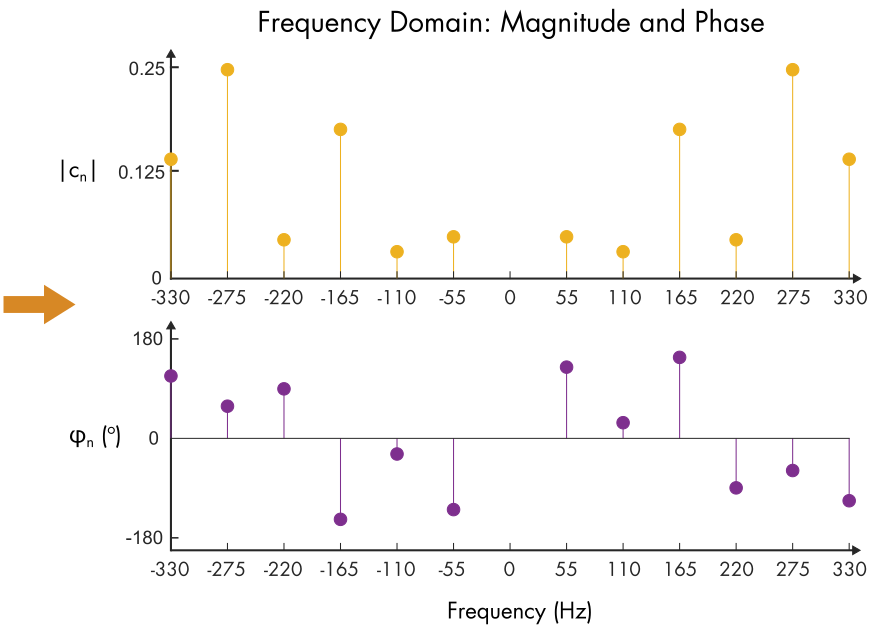

*A simplified guitar chord in the time and frequency domains. First pane: the 2L periodic function in the time domain. Second pane: the magnitude and phase of the complex coefficients *$c_n$*. Because *$y(t)$ *is real, the coefficients are mirrored at negative frequencies.*

In this chord, you can see that the C# (275 Hz) is dominant. 

Because the audio signal produced by a guitar is largely periodic, a complex Fourier series provides good estimates for the frequency domain. But how can you compute the frequency domain for a function that is not periodic?

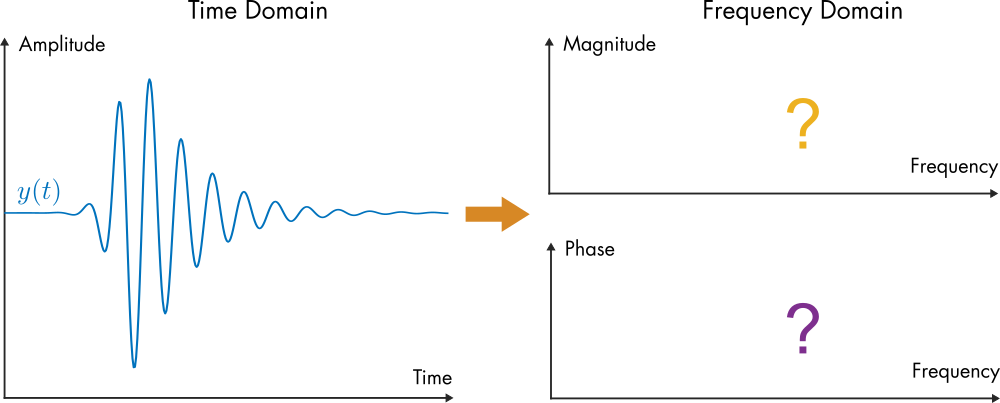

*What will the frequency domain plots of *$y(t)$* look like?*

### **Estimating a Non-Periodic Function with Fourier Series**

It is possible to assume a finite domain (of length $2L$) that encompasses most of a non-periodic function and compute the Fourier series coefficients. This will indeed provide information about the frequency content of the function. However, it will never offer a true representation of the original function, since, by definition, the Fourier series is periodic (with period $2L$).

    **Activity. **The plots below illustrate complex Fourier series estimates of a non-periodic function. 

- Adjust `L` to change the size of the domain on which the Fourier series is computed.

- Adjust` N` to change the number of frequencies used in the complex Fourier series.

**Task 1. **Press **Show plot**. Observe the four plots. 

- The plot labeled **Fourier Series Reconstruction** shows the function modeled by the Fourier series (as opposed to the original function, $y(t)$, graphed in the first plot).

- The first frequency domain plot shows the magnitude of the complex series coefficients, $|c_n|$. 

- The second frequency domain plot with the y-axis label $\angle c_n$ shows the phase angle in radians. 

**Task 2. **Set `L = 1` and `N = 10`. Is $y(t)$ accurately captured?

**Task 3.** Set `L = 2` and then `L = 3`. Does this improve the estimate?

**Task 4. **With `L = 3` and `N = 10`, are there enough modes to capture most of the frequency content? If not, increase the number of modes `N` until the majority of the frequency content is captured.

**Task 5. **Expand the domain to `L = 5`. Increase the number of modes `N `until the majority of the frequency content is captured.

L = 1; % The domain half-width
N = 10; % The number of Fourier modes to use in the series
 
fourierEstimateSech(L,N) % Helper function that creates the plots

**  Reflect.** 

- If you want to increase the frequency domain resolution (i.e., make the stems closer to each other), should you increase the domain width `L` or the number of frequencies `N`?

- In the case where `L = 5`, no periodic copies of the function are visible in the plot of the reconstruction, $y_r$. In this case, do periodic copies exist in $y_r$?

- How large would the domain need to be for there to be no periodic copies?

- In the case where there are no more periodic copies, what will the resolution of the frequency domain be (i.e., how close will the stems be to each other)?

While the complex Fourier series can provide a good estimate, it will never perfectly capture a non-periodic function. For this to be possible, the domain on which the Fourier series is computed must become infinitely large ($L \to \infty$), which is not compatible with the Fourier series definition.

The Fourier transform, on the other hand, is capable of analytically representing the entire function in the frequency domain.

## Definition

The Fourier transform of a function $f(t)$ is


$$\hat{f}(\omega) = \int_{-\infty}^\infty f(t) e^{-i\omega t} \ dt$$


In this definition, $\omega$ is the angular frequency. To obtain the original signal $f$ from $\hat{f}$, you can use the inverse Fourier transform. The inverse transform has the complementary definition


$$f(t) = \frac{1}{2 \pi} \int_{-\infty}^\infty \hat{f}(\omega) e^{i\omega t} \ dt$$


There are several alternative definitions to the Fourier transform. This definition has been selected because it matches the definitions used by the Symbolic Math Toolbox functions for the Fourier transform: [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) and [`ifourier`](https://www.mathworks.com/help/symbolic/sym.ifourier.html). 

## Analytic Evaluation of the Fourier Transform  

The Fourier transform can be computed by hand using the definition or by appealing to a table. Another alternative is to use the [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) function from the Symbolic Math Toolbox. The example below shows two of these methods for a Gaussian. The Gaussian function is unique because its Fourier transform is another Gaussian.

 **Example. **A simple Gaussian function with a single parameter $a$ is


$$y(t) = e^{- a t^2}$$


Gaussian curves have a well-defined and (relatively) easy to compute Fourier transform. 


$$\begin{array}{rl}
\hat{y}(\omega) &= \int_{-\infty}^\infty e^{-a t^2} e^{-i\omega t} \ dt
\\
&= \int_{-\infty}^\infty e^{- a( t^2 + i\omega t/a - \omega^2/(4a^2)) - \omega^2/(4a)} \ dt
\\
&= e^{ - \frac{\omega^2}{4 a}} \int_{-\infty}^\infty e^{- a (t+i\omega/(2a))^2} \ dt
\\
&= \sqrt{\frac{\pi}{a}} e^{ - \frac{ \omega^2}{4a}} 
\end{array}$$


You can validate the result by computing the Fourier series using the [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) function from the Symbolic Toolbox. 

**Task. **Run this section to compute the Fourier transform.

  **Pro-tip.** To run a section quickly, use the keyboard shortcut, **Ctrl**+**Enter**.

syms t omega % Define the symbolic variables
syms a positive % a is a positive constant
y = exp(-a*t^2) % Define the function
yhat = fourier(y,t,omega) % Compute the Fourier transform

**Task. **The function $y$ and its Fourier transform $\hat{y}$ are plotted below. Run this section to show the plot. Then, use the slider below to adjust the value of the parameter $a$ and regenerate the plot.

% Substitute a value for a
aValue = 2;
transformPlot(aValue) % Helper function that generates the plot

**  Reflect.** 

- How does $y(t)$ change as $a$ is increased?

- How does $\hat{y}(t)$ change as $a$ is increased?

- Based on this plot, what general relationship does there appear to be between a function in the time domain and it's frequency content?

## **Analytic Approximation of a Real Signal**

A guitar's audio signal is not actually periodic. In fact, it amplifies quickly, and then decays exponentially.

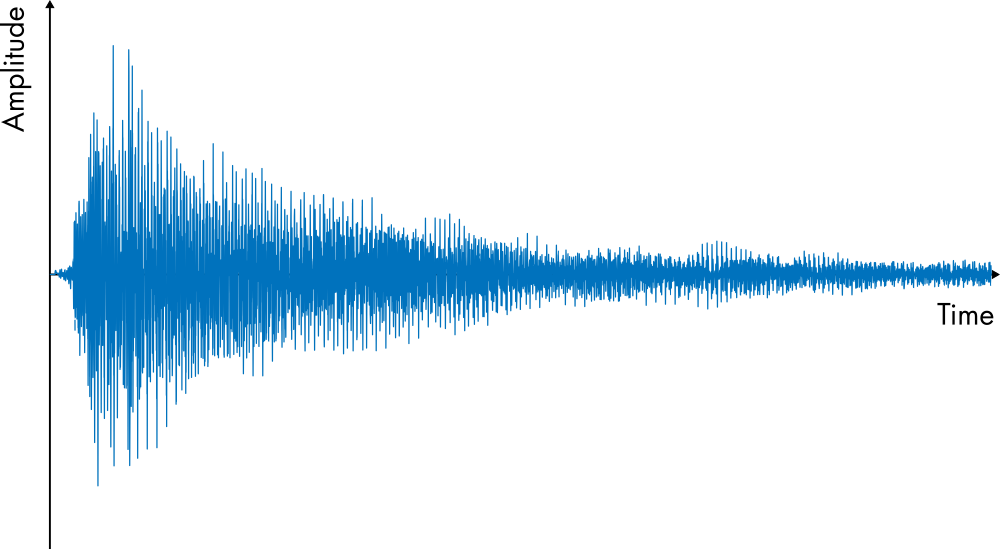

*Guitar "A" note signal in the time domain*

In the previous scripts, a small window of the signal was analyzed with the Fourier series. To analyze the full non-periodic signal, it is useful to apply the Fourier transform. While the guitar audio signal contains many harmonics and has some ramp-up time, it can be reasonably estimated by the product of a single frequency and a decaying exponential:


$$y(t) = e^{-at} \sin ( 2 \pi \omega_0 t )$$


where $a$ is the decay rate and $\omega_0$ is the fundamental frequency. For the guitar A note, a reasonable choice for $\omega_0$ is $2 \pi \cdot 110$, which corresponds to 110 Hz. This function could easily be modified to better represent the real audio signal by adding additional sine terms for the harmonics.

  ** Activity. **In this activity, you will construct, plot, and analyze the frequency content of the signal $y(t)$.

**Task 1.** Using the predefined values of `a,` `omega0`, and `t`, compute $y(t)$ as a vector `y `so it can be plotted.

**Hint.** Since `t` is a vector, you should use element-wise multiplication: **.***

omega0 = 2*pi*110; % angular frequency corresponding to 110 Hz
a = 1.5; % Decay rate (per second)
t = 0:1/44.1e3:3; % Time variable
% Compute y here



If correct, `y` should contain a vector of values:

**Task 2. **Plot the signal `y` against `t` using [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html). Label the axes using [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html) and [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html).

figure % Creates a new figure
% Plot y against t here



The function $y(t)$ is not in an acceptable form for analysis with the Fourier transform. The exponential factor $e^{-t}$ will grow exponentially for negative times, preventing the integral from converging. This is also not very reaslitic since real audio signals do not grow in "negative time." To cut the function off at a specified time, $t_c$, you can use the Heaviside step function, $H(t)$:


$$y_c(t) =  H(t-t_c) e^{-a(t-t_c)} \sin ( 2 \pi \omega_0 t )$$


Recall that 


$$H(t) = \left\{ \begin{array}{rl} 0 \ \ & t < 0 \\ 1 \ \ & t \geq 0 \end{array} \right.$$


**Task 3. **Using the pre-defined values `a,` `omega0`, `tc`, and `t`, compute `yc` as a vector so it can be plotted. For the Heaviside step function, you can use the built in function [`heaviside`](https://www.mathworks.com/help/symbolic/heaviside.html).

tc = 0.5; % Cutoff time
% Compute yc here
yc = NaN


**Task 4. **Plot `yc` against `t` to view the signal in the time domain. What do you expect this signal will look like in the frequency domain?

% Create your plot here



If correct, your plot should appear as

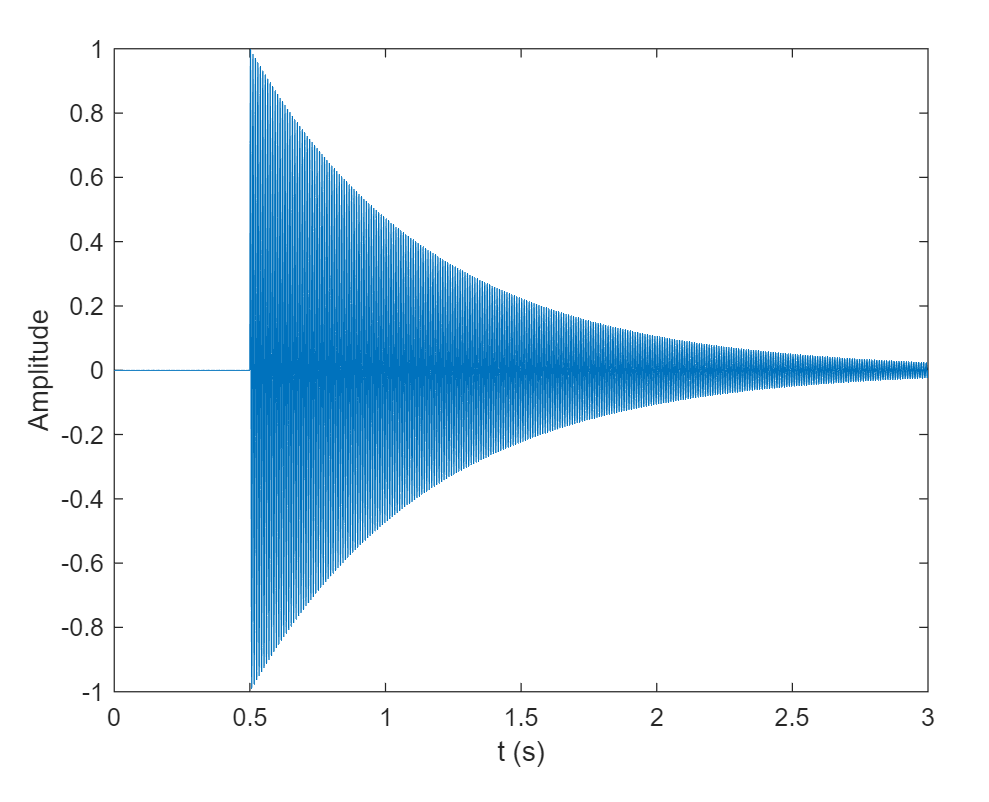

**Task 5. **Run this section to play `yc` as a sound.

Fs = 1/(t(2)-t(1)); % The sample rate
soundsc(yc,Fs) % Play the sound

**Task 6. **The Fourier transform of $y_c$ has an analytic expression. Test your integration skill: compute the Fourier transform of $y_c(t)$ by hand using the definition 


$$\hat{y_c}(\omega) = \int_{-\infty}^\infty y_c(t) e^{-i\omega t} \ dt$$


**Hint**: rewrite the sine function in terms of complex exponentials and split up the domain based on the Heaviside step function.

Alternatively, you can compute the Fourier transform using the Symbolic Math Toolbox. 

**Task 7. **Define `yc` as a symbolic expression. Start by [defining a symbolic variable](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html) for $t$ using

Then, express $y_c$ in terms of `t`. As part of the expression, you can use the pre-defined constant values `a,` `omega0`, and `tc`. This expression should be identical to the one you used in **Task 3**. The difference is that the input, `t`, is now a symbolic variable instead of a vector.

% Write your code here



**Task 8.** To compute the Fourier transform of `yc`, use the [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) function from the Symbolic Math Toolbox. Define the result as `yhat`.

% Compute the Fourier transform here



**Task 9. **Generate a plot of the magnitude of `yhat` $|\hat{y}|$ on the interval $\omega$ in `[0,1250]`. To generate a plot of a symbolic expression, use [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html) with the syntax

where `f` contains the symbolic expression to be plotted and `xinterval` contains the domain limits. After creating the plot, set the vertical axis limits to `[0,0.25]` using [`ylim`](https://www.mathworks.com/help/matlab/ref/ylim.html). Also label the axes.

% Create your plot of yhat here



**  Reflect.** 

- After plotting the magnitude $| \hat{y} |$, you can see a peak at 110 Hz ($\approx$691 rad/s). Which factor in the function generates this peak?

- What would the plot of the magnitude of the Fourier coefficients of a pure 110 Hz sine wave look like?

- How is the plot similar to and different from the pure sine wave Fourier coefficient plot?

- What effects do the Heaviside and exponential decay functions have on the frequency domain?

## Carrier Wave Modulation

You can think of the signal analyzed in the previous activity as having two distinct components: an *envelope* that changes slowly with time and an underlying "high" frequency (110 Hz) wave.

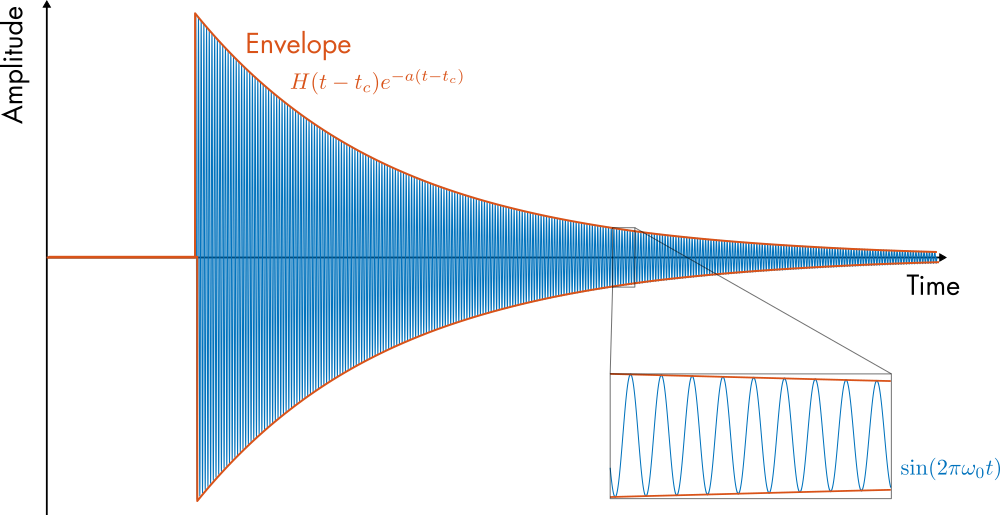

*Illustration of the two fundamental components of the generated audio signal in the time domain.*

This type of mixed signal is common in signal transmission applications. A high frequency carrier wave gives a signal its fundamental frequency. The carrier is modulated at a lower frequency to encode information. For example, amplitude modulation is used in AM radio. The fundamental frequency of the radio signal is modulated (in amplitude) to match the transmitted audio signal. For AM radio, the carrier frequency is between 540 and 1600 kHz. When you tune your radio to a station, you tune it to the carrier frequency. Then, the receiver picks up the audio information from the slower modulation. 

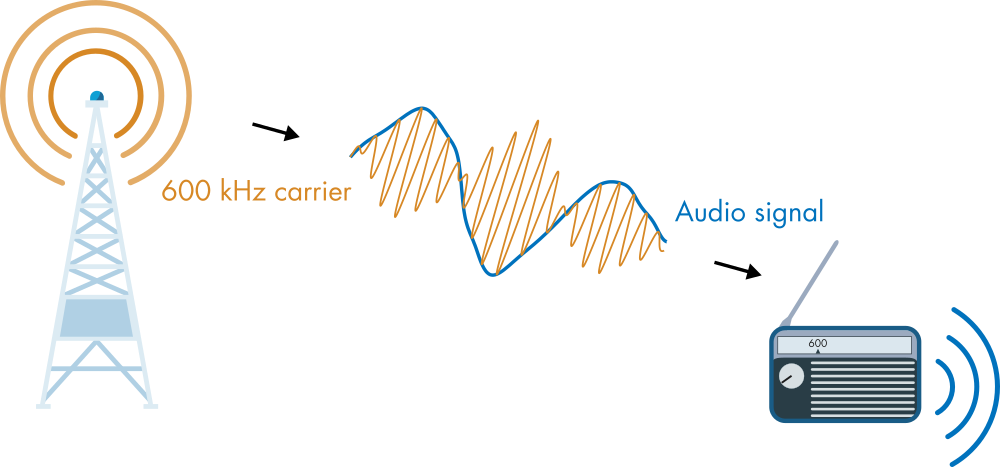

*An AM radio tuned to 600 kHz will pick up the amplitude modulation of the 600 kHz carrier and use it to drive the speaker.*

To prevent interference, the modulation is limited to a maximum frequency of 5 kHz. This frequency is not sufficient to fully reproduce audio signals. This is one reason why AM radio has lower audio quality than FM radio. 

### The Frequency Domain

Consider the characteristics of the modulated AM signal shown in the figure above. What do you expect the signal will look like in the frequency domain? How will the frequency content change if the carrier frequency is changed? In this section, you will analyze modulated signals using the Fourier transform.

When applying the continuous Fourier transform, you must work with functions that have a well-defined (analytic) Fourier transform. There are several such functions, but one of the easiest to work with is the Gaussian-modulated sinusoidal function:


$$g(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


This function doesn't represent any particular real signal, but is simple and can help you quickly develop intuition about how changes to the carrier and modulation affect the signal's frequency content.

  ** Activity. **The plot below shows the Gaussian-modulated sinusoidal function in the time domain. Run the section to show the plot. Then, adjust each parameter and notice the changes to the waveform. 

A = 1.5; % Amplitude
f0 = 15; % Carrier frequency (Hz)
c = 0.1; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
sineGaussPlot(A,omega0,t0,c)

**  Reflect.** 

- What do you think the function will look like in the frequency domain? (i.e., what will the plot of $\hat{f}$ look like?)

- As each of the parameters ($A$, $\omega_0$, $c$, $t_0$) is increased, how do you expect the frequency domain plot to change?

 **Exercise. **In this exercise, you will compute the Fourier transform of $g(t)$.

**Task 1. **(Optional) Compute the Fourier transform of a simplified version of $g(t)$by hand:


$$g(t) = \sin(  t ) e^{- \frac{t^2}{2  } }$$


**Hint**: rewrite the sine function in terms of complex exponentials. Then, expand the terms and complete the square.

**Task 2. **Use the Symbolic Math Toolbox to define the original function:


$$g(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


Use the pre-defined symbolic variables in your expression for `g`. 

% Predefined symbolic variables
syms t omega real
syms omega_0 t_0 c A positive
% Write an expression for g here



**Task 3**. Use [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) to compute the Fourier transform of `g` and store the result in `ghat`.

% Compute the Fourier transform here



**Task 4. **Use the [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html) function to simplify `ghat`.

% Simplify ghat here



**Real and Imaginary Components**

The functional form of $\hat{g}$ is a little complicated. It's helpful to plot the result to develop some intuition about how changes to the parameters affect the frequency content.

  ** Activity. **In this activity, you will review how changes to the function $g$ affect the frequency domain by plotting the real and imaginary components of $\hat{g}$.

**Task 1. **Click **Show plots**.

% This plots the Gaussian-modulated sinusoid and its Fourier transform
A = 1.5; % Amplitude
f0 = 15; % Carrier frequency (Hz)
c = 0.1; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
 

% Compute ghat 
omega = linspace(-250,250,5e3);
ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
                            exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));
sineGaussComplexPlot(omega,ghat,A,omega0,t0,c) % Helper function that generates the plot

**Task 2. **Increase each parameter independently. How does the frequency domain plot change as you increase each?

**Task 3. **You should notice two very similar copies in the frequency domain at negative and positive frequencies. Set $t_0$ to a relatively small value to make the differences more obvious. How do these copies seem to be related?

**  Reflect.** 

- How does changing the carrier frequency affect the frequency domain plot?

- How does expanding the Gaussian width affect the frequency domain? Does this make sense?

- Why is there a negative frequency component? Does it have real-world significance?

**Magnitude and Phase**

Plotting the real and imaginary components of the Fourier transform $\hat{f}$ are helpful for understanding the underlying functional components. Just as with complex Fourier series, a negative frequency domain component is required to reconstruct a real function. This results from using the complex exponential, which contains imaginary components that must be "cancelled out" to produce a real function. However, plots of the magnitude and phase are typically more helpful for understanding the frequency domain.

  ** Activity. **In this activity, you will review how changes to the function $g$ affect the frequency domain by plotting the magnitude and phase of $\hat{g}$.

**Task 1. **Click **Show plots**.

% This plots the Gaussian-modulated sinusoid and it's Fourier transform
A = 1.5; % Amplitude
f0 = 15; % Carrier frequency (Hz)
c = 0.1; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
 

sineGaussMagPhasePlot(A,omega0,t0,c) % Helper function that generates the plot

**Task 2. **Increase each parameter independently. How do the frequency domain plots change you increase each?

**  Reflect.** 

- Review the phase plot $\angle g$. The phase is estimated using the angle function, which always returns an angle between $-\pi$ and $\pi$. Is the phase of the analytic function actually between $-\pi$ and $\pi$? Recall that the phase of a complex number $Ae^{i \phi}$ is $\phi$.

- Which parameters affect the magnitude plot in the frequency domain? What changes?

- Which parameters affect the phase plot? What changes?

[⇦ Fourier Analysis Overview](matlab: OpenOverview)

function fourierEstimateSech(L,Nmodes)
    % This function creates a figure that illustrates
    % how the Fourier series only models a finite domain

    % Parameters
    tf = 12;
    ts = 2;
    tmid = 6;
    sigma = 0.2;
    freq = 1.6;
    Nt = 1000;
    
    % Domain and function
    ylims = [-1,1];
    tlims = [0,tf];
    freqLims = [-4,4];
    t = linspace(tlims(1),tlims(2),Nt);
    sechValue = 2./(exp((0.2*t-ts)/sigma) + exp(-(t-ts)/sigma));
    y = sin(2*pi*freq*t).*sechValue/1200;

    % Extract the correct interval
    dLims = round( (tmid + [-L,L])*Nt/tf );
    dIdx = dLims(1):dLims(end);
    yc = y(dIdx);
    tc = t(dIdx);

    % Estimate coefficients using trapezoid rule
    nvec = -Nmodes:1:Nmodes;
    freq = nvec/(2*L);
    c = zeros(1,numel(nvec));
    for k = nvec + Nmodes + 1
        c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
    end

    % Compute the Fourier series estimate
    ft = zeros(size(t));
    for k = 1:numel(nvec)
        ft = ft + c(k)*exp(1i*pi/L*nvec(k).*t);
    end

    % Create the figure and subplots
    colors = lines(4);
    figure("OuterPosition",[1,1,800,400])
    subplot(2,2,1)
    plot(t,y,"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    ylim(ylims)
    xlim(tlims)
    ylabel("$y(t)$ (original)","Interpreter","latex")
    title("Time Domain","Interpreter","latex")

    subplot(2,2,3)
    plot(t,real(ft),"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    xlim(tlims)
    ylim(ylims)
    xlabel("Time (s)","Interpreter","latex")
    ylabel("$y_r(t)$ (reconstructed)","Interpreter","latex")
    title("Fourier Series Reconstruction","Interpreter","latex")

    subplot(2,2,2)
    stem(freq,abs(c),"Filled","Color",colors(3,:))
    xlim(freqLims)
    ylabel("$| c_n |$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")

    subplot(2,2,4)
    stem(freq,angle(c),"Filled","Color",colors(4,:))
    xlim(freqLims)
    xlabel("Frequency (Hz)","Interpreter","latex")
    ylabel("$\angle c_n$","Interpreter","latex")

end


function transformPlot(a)
    % Plots the transform of the defined function

    t = linspace(-10,10,500);
    y = exp(-a*t.^2); % Define the function
    omega = linspace(-10,10,500);
    yhat = sqrt(pi/a)*exp((-omega.^2/(4*a)));

    % Create the plots
    figure("Position",[1 1 800 300])
    
    subplot(1,2,1)
    plot(t,y,"LineWidth",1)
    ylim([0,2])
    xlabel("$t$","Interpreter","latex")
    ylabel("$y(t)$","Interpreter","latex")

    subplot(1,2,2)
    plot(omega,yhat,"LineWidth",1)
    ylim([0,2])
    xlabel("$\omega$","Interpreter","latex")
    ylabel("$\hat{y}(t)$","Interpreter","latex")

end

function sineGaussPlot(A,omega0,t0,c)
    % Plots a Gaussian modulated sinusoidal function
    % with the Gaussian modulation displayed separately
    
    t = linspace(0,1,1e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
    modulation = A*exp(-(t-t0).^2/(2*c^2));

    figure
    plot(t,g,t,modulation,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
end

function sineGaussComplexPlot(omega,ghat,A,omega0,t0,c)
    % Creates a plot of the Gaussian modulated sinusoid

    % Compute g
    t = linspace(0,1,5e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

    % Plots a Gaussian modulated sinusoid
    % in time and frequency domains (real/imaginary part)
    figure("Position",[1 1 800 400])
    subplot(1,2,1)
    plot(t,g,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    
    subplot(1,2,2)
    hold on
    plot(omega,real(ghat),"LineWidth",0.75)
    plot(omega,imag(ghat),"LineWidth",0.75)
    ylim([-0.5,0.5])
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{g}$","Interpreter","latex")
    legend("Re$(\hat{g})$","Im$(\hat{g})$","Interpreter","latex");
    title("Frequency Domain","Interpreter","latex")
end

function sineGaussMagPhasePlot(A,omega0,t0,c)
    % Creates a plot of the Gaussian modulated sinusoid
    % and its Fourier transform
    
    % Compute g
    t = linspace(0,1,5e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

    % Compute ghat 
    omega = linspace(-250,250,5e3);
    ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
                                exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    % Plots a Gaussian modulated sinusoid
    % in time and frequency domains (mag/phase part)
    figure("Position",[1 1 800 600])
    
    subplot(2,2,[1,3])
    plot(t,g,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    
    colors = lines(4);
    subplot(2,2,2)
    hold on
    plot(omega,abs(ghat),"Color",colors(3,:),"LineWidth",1)
    ylim([-0.5,0.5])
    xlim([omega(1),omega(end)])
    ylabel("$|\hat{g}|$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")

    subplot(2,2,4)
    hold on
    plot(omega,angle(ghat),"Color",colors(4,:),"LineWidth",1)
    ylim([-4,4])
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\angle \hat{g}$ (rad)","Interpreter","latex")
end

% Suppressed warnings
%#ok<*NASGU> 